Store continuous features in a seperate table.

num = vartype('numeric')

num = 	table vartype subscript:

		Select table variables matching the type 'numeric'

	See Access Data in a Table.



ctdN = ctd(1:1000000, num)

ctdN = 1000000×3 table
    distance_from_home    distance_from_last_transaction    ratio_to_median_purchase_price
    __________________    ______________________________    ______________________________

          57.878                     0.31114                             1.9459           
           10.83                     0.17559                             1.2942           
          5.0911                     0.80515                            0.42771           
          2.2476                         5.6                            0.36266           
          44.191                     0.56649                             2.2228           
          5.5864                      13.261                           0.064768           
           3.724                     0.95684                            0.27846           
          4.8482                     0.32074           

Generate data quality report for continuous features.

Features1=cell(width(ctdN),1);
countN=zeros(width(ctdN),1);
missingN=zeros(width(ctdN),1);
cardN = zeros(width(ctdN), 1);
minN=zeros(width(ctdN),1);
perc25=zeros(width(ctdN),1);
meanN=zeros(width(ctdN),1);
medianN=zeros(width(ctdN),1);
perc75=zeros(width(ctdN),1);
maxN=zeros(width(ctdN),1);
stdN=zeros(width(ctdN),1);

for col =1: width(ctdN)
     Features1(col,1) = ctdN.Properties.VariableNames(col);
     countN(col,1)=height(ctdN.(col));
     missingN(col,1)=100*sum(ismissing(ctdN.(col)))/height(ctdN);
     cardN(col,1)=height(groupsummary(ctdN,col));
     minN(col,1)=min(ctdN.(col));
     perc25(col,1)=prctile(ctdN.(col),25);
     meanN(col,1)=mean(ctdN.(col),'omitnan');
     medianN(col,1)=median(ctdN.(col),'omitnan');
     perc75(col,1)=prctile(ctdN.(col),75);
     maxN(col,1)=max(ctdN.(col));
     stdN(col,1)=std(ctdN.(col),'omitnan');
end

QRctdN=table(Features1,countN,missingN,cardN,minN,perc25,meanN,medianN,perc75,maxN,stdN)

QRctdN = 3×11 table
                Features1                 countN    missingN    cardN       minN       perc25     meanN     medianN    perc75    maxN      stdN 
    __________________________________    ______    ________    _____    __________    _______    ______    _______    ______    _____    ______

    {'distance_from_home'            }    1e+06        0        1e+06     0.0048744      3.878    26.629     9.9678    25.744    10633    65.391
    {'distance_from_last_transaction'}    1e+06        0        1e+06    0.00011828    0.29667    5.0365    0.99865    3.3558    11851    25.843
    {'ratio_to_median_pur

Store categorical features in a seperate table.

cat = vartype('categorical')

cat = 	table vartype subscript:

		Select table variables matching the type 'categorical'

	See Access Data in a Table.



ctdC = ctd(1:1000000, cat)

ctdC = 1000000×5 table
    repeat_retailer    used_chip    used_pin_number    online_order    fraud
    _______________    _________    _______________    ____________    _____

          1.0             1.0             0.0              0.0          0.0 
          1.0             0.0             0.0              0.0          0.0 
          1.0             0.0             0.0              1.0          0.0 
          1.0             1.0             0.0              1.0          0.0 
          1.0             1.0             0.0              1.0          0.0 
          1.0             0.0             0.0              0.0          0.0 
          1.0             0.0             0.0              1.0          0.0 
          1.0             0.0             1.0              0.0          0.0 
          0.0             0.0       

Generate data quality report for categorical features.

 Features2=cell(width(ctdC),1);
 countC=zeros(width(ctdC),1);
 missingC=zeros(width(ctdC),1);
 cardC=zeros(width(ctdC), 1);
 modeC=categorical(zeros(width(ctdC), 1));
 modeC_freq=zeros(width(ctdC), 1);
 modeC_per=zeros(width(ctdC), 1);
 modeC2=categorical(zeros(width(ctdC), 1));
 modeC2_freq=zeros(width(ctdC), 1);
 modeC2_per=zeros(width(ctdC), 1);
 for col =1: width(ctdC)
     Features2(col,1)=ctdC.Properties.VariableNames(col);
     countC(col,1)=height(ctdC.(col));
     missingC(col,1)=100*sum(ismissing(ctdC.(col)))/height(ctdC);
     cardC(col,1)=height(groupsummary(ctdC,col));
     [modeC(col,1),modeC_freq(col,1)]=mode(ctdC.(col));
     modeC_per(col, 1)=100*(modeC_freq(col, 1)/height(ctdC.(col)));
     [modeC2(col,1),modeC2_freq(col,1)]=mode(ctdC.(col)((ctdC.(col))~=mode(ctdC.(col))));
     modeC2_per(col, 1)=100*(modeC2_freq(col, 1)/height(ctdC.(col)));
end

QRctdC=table(Features2,countC,missingC,cardC,modeC,modeC_freq,modeC_per,modeC2,modeC2_freq,modeC2_per)

QRctdC = 5×10 table
         Features2         countC    missingC    cardC    modeC    modeC_freq    modeC_per    modeC2    modeC2_freq    modeC2_per
    ___________________    ______    ________    _____    _____    __________    _________    ______    ___________    __________

    {'repeat_retailer'}    1e+06        0          2       1.0     8.8154e+05     88.154       0.0      1.1846e+05       11.846  
    {'used_chip'      }    1e+06        0          2       0.0      6.496e+05      64.96       1.0       3.504e+05        35.04  
    {'used_pin_number'}    1e+06        0          2       0.0     8.9939e+05     89.939       1.0      1.0061e+05     

Data visualization for descriptive features after cleaning

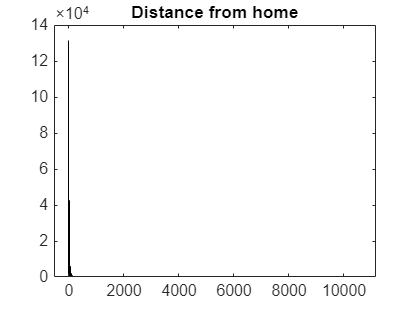

histogram(ctd.distance_from_home);
title("Distance from home");

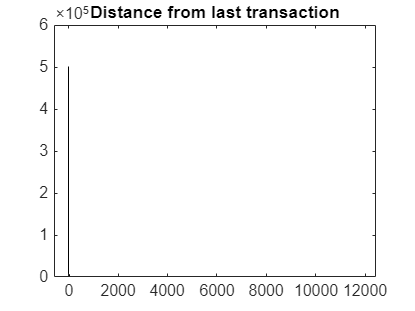


histogram(ctd.distance_from_last_transaction);
title("Distance from last transaction");

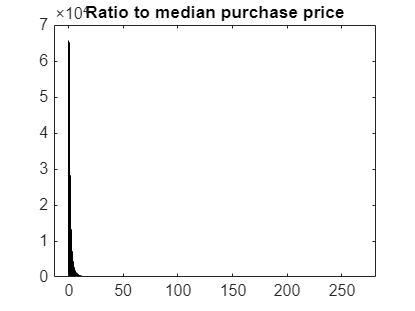


histogram(ctd.ratio_to_median_purchase_price);
title("Ratio to median purchase price");

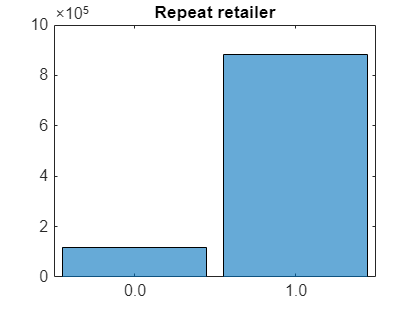


histogram(ctd.repeat_retailer);
title("Repeat retailer");

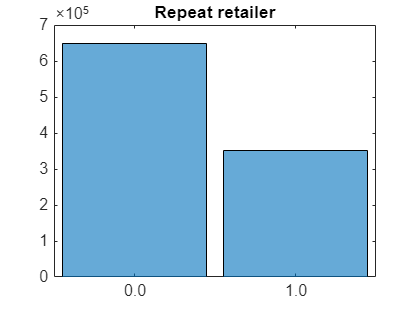


histogram (ctd.used_chip);
title("Repeat retailer");

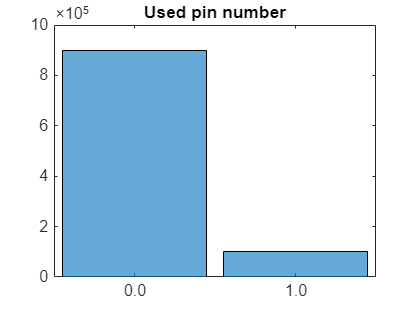


histogram (ctd.used_pin_number);
title("Used pin number");

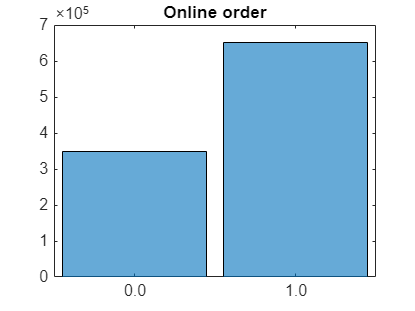


histogram (ctd.online_order);
title("Online order");

Seperate fraud and nonfraud dataset

ctdnf = ctd(ctd.fraud == '0.0', :);
ctdf = ctd(ctd.fraud == '1.0', :);  

Create a subset of the dataset

%456,298 nonfraud
%43,701 fraud
% nonfraud / fraud ratio = 91% / 9%
part1=cvpartition(height(ctdnf),'HoldOut',0.50)

part1 = Hold-out cross validation partition
   NumObservations: 912597
       NumTestSets: 1
         TrainSize: 456299
          TestSize: 456298
          IsCustom: 0


idxtest1=test(part1)

idxtest1 = 912597×1 logical array
   1
   1
   1
   0
   0
   1
   0
   0
   0
   1



ctd_nf_sub=ctdnf(idxtest1,:)

ctd_nf_sub = 456298×8 table
    distance_from_home    distance_from_last_transaction    ratio_to_median_purchase_price    repeat_retailer    used_chip    used_pin_number    online_order    fraud
    __________________    ______________________________    ______________________________    _______________    _________    _______________    ____________    _____

          57.878                      0.31114                            1.9459                     1.0             1.0             0.0              0.0          0.0 
           10.83                      0.17559                            1.2942                     1.0             0.0             0.0              0.0          0.0 
          5.0911               


part2=cvpartition(height(ctdf),'HoldOut',0.50)

part2 = Hold-out cross validation partition
   NumObservations: 87403
       NumTestSets: 1
         TrainSize: 43702
          TestSize: 43701
          IsCustom: 0


idxtest2=test(part2)

idxtest2 = 87403×1 logical array
   0
   0
   1
   1
   0
   0
   1
   1
   1
   1



ctd_f_sub=ctdf(idxtest2,:)

ctd_f_sub = 43701×8 table
    distance_from_home    distance_from_last_transaction    ratio_to_median_purchase_price    repeat_retailer    used_chip    used_pin_number    online_order    fraud
    __________________    ______________________________    ______________________________    _______________    _________    _______________    ____________    _____

          15.695                       175.99                           0.85562                     1.0             0.0             0.0              1.0          1.0 
          26.711                        1.552                            4.6036                     1.0             1.0             0.0              1.0          1.0 
          21.126                 


% concatinating the newly created subset of non fraud observations with our
% fraud observations to create our dataset
ctd_sub=vertcat(ctd_f_sub,ctd_nf_sub)

ctd_sub = 499999×8 table
    distance_from_home    distance_from_last_transaction    ratio_to_median_purchase_price    repeat_retailer    used_chip    used_pin_number    online_order    fraud
    __________________    ______________________________    ______________________________    _______________    _________    _______________    ____________    _____

          15.695                       175.99                           0.85562                     1.0             0.0             0.0              1.0          1.0 
          26.711                        1.552                            4.6036                     1.0             1.0             0.0              1.0          1.0 
          21.126                  

Undersampling

% creating a subset of the non fraud observations to match the amount of
% fraud observations
part=cvpartition(height(ctdnf),'HoldOut',0.096)

part = Hold-out cross validation partition
   NumObservations: 912597
       NumTestSets: 1
         TrainSize: 824988
          TestSize: 87609
          IsCustom: 0


idxtest=test(part)

idxtest = 912597×1 logical array
   0
   0
   1
   0
   0
   0
   1
   0
   0
   0



ctd_nf_new=ctdnf(idxtest,:)

ctd_nf_new = 87609×8 table
    distance_from_home    distance_from_last_transaction    ratio_to_median_purchase_price    repeat_retailer    used_chip    used_pin_number    online_order    fraud
    __________________    ______________________________    ______________________________    _______________    _________    _______________    ____________    _____

          5.0911                      0.80515                           0.42771                     1.0             0.0             0.0              1.0          0.0 
           3.724                      0.95684                           0.27846                     1.0             0.0             0.0              1.0          0.0 
          6.1947                


% concatinating the newly created subset of non fraud observations with our
% fraud observations to create our dataset
ctd_under=vertcat(ctdf,ctd_nf_new)

ctd_under = 175012×8 table
    distance_from_home    distance_from_last_transaction    ratio_to_median_purchase_price    repeat_retailer    used_chip    used_pin_number    online_order    fraud
    __________________    ______________________________    ______________________________    _______________    _________    _______________    ____________    _____

           2.132                       56.372                            6.3587                     1.0             0.0             0.0              1.0          1.0 
          3.8031                       67.241                            1.8729                     1.0             0.0             0.0              1.0          1.0 
          15.695                

Oversampling

x = 40000;

% This if statement checks if our prespecified number of desired rows is
% bigger than the actual count of rows in the dataset
if x > height(ctdf)
    error('x should not exceed the number of rows in the dataset.');
end

% using the function randomperm, we loop through our table that includes
% only fraud incidents and store random rows in randomIndices
randomIndices = randperm(height(ctdf), x);

% we store the results of randomIndices into the table called ctdf_rand
ctdf_rand = ctdf(randomIndices, :);

% concatinating the fraud only table with the randomly chosen fraud rows to
ctd_fandrand=vertcat(ctdf,ctdf_rand)

ctd_fandrand = 127403×8 table
    distance_from_home    distance_from_last_transaction    ratio_to_median_purchase_price    repeat_retailer    used_chip    used_pin_number    online_order    fraud
    __________________    ______________________________    ______________________________    _______________    _________    _______________    ____________    _____

           2.132                       56.372                            6.3587                     1.0             0.0             0.0              1.0          1.0 
          3.8031                       67.241                            1.8729                     1.0             0.0             0.0              1.0          1.0 
          15.695             


% creating a subset of the not fraud observations, the exact amount of
% which is equal to the newly manufactured fraud dataset
part=cvpartition(height(ctdnf),'HoldOut',0.1396)

part = Hold-out cross validation partition
   NumObservations: 912597
       NumTestSets: 1
         TrainSize: 785199
          TestSize: 127398
          IsCustom: 0



idxtest=test(part)

idxtest = 912597×1 logical array
   0
   0
   0
   0
   0
   0
   1
   0
   1
   0



ctd_nf_over=ctdnf(idxtest,:)

ctd_nf_over = 127398×8 table
    distance_from_home    distance_from_last_transaction    ratio_to_median_purchase_price    repeat_retailer    used_chip    used_pin_number    online_order    fraud
    __________________    ______________________________    ______________________________    _______________    _________    _______________    ____________    _____

           3.724                      0.95684                          0.27846                      1.0             0.0             0.0              1.0          0.0 
         0.87663                       2.5036                            1.517                      0.0             0.0             0.0              0.0          0.0 
          11.085              


%concatinating the manufactured fraud dataset with the subset of not fraud
%observations to create our ready to use dataset 
ctd_over=vertcat(ctd_fandrand,ctd_nf_over)

ctd_over = 254801×8 table
    distance_from_home    distance_from_last_transaction    ratio_to_median_purchase_price    repeat_retailer    used_chip    used_pin_number    online_order    fraud
    __________________    ______________________________    ______________________________    _______________    _________    _______________    ____________    _____

           2.132                       56.372                            6.3587                     1.0             0.0             0.0              1.0          1.0 
          3.8031                       67.241                            1.8729                     1.0             0.0             0.0              1.0          1.0 
          15.695                 

Data visualization of sampling 

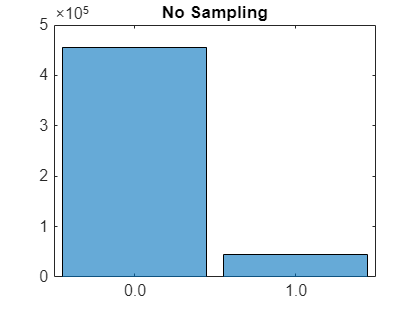

histogram(ctd_sub.fraud);
title("No Sampling");

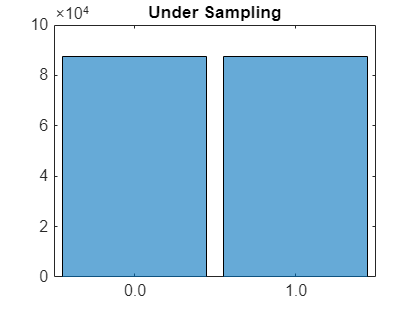


histogram(ctd_under.fraud);
title("Under Sampling");

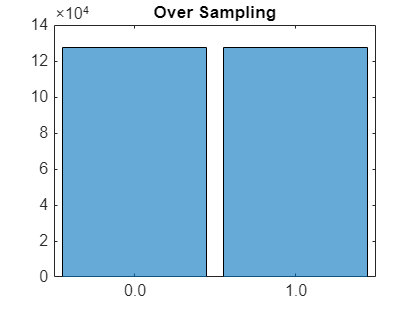


histogram(ctd_over.fraud);
title("Over Sampling");